# Roots of a quadratic equation

The general form of a quadratic equation is :


$$ax^2+bx+c=0$$


it is possible to solve for the roots (x values where y=0) using the quadratic equation. You can also solve numerically using this script. Just input the values for a, b and c in the code below.

This might be useful for doing assignments in CH261

Ka=10^-4.919; AT=0.003; 
a=1; b=Ka; c=-Ka*AT;
t=roots([a b c]); %finds the roots
t=t(imag(t)==0); %sets any imaginary roots to zero
% display the positive real root

t=t(t>0)

t = 1.8420e-04


% take minus log in case that might be useful (pH for example)

pt=-log10(t)

pt = 3.7347

14-pt

ans = 10.2653

Make plot

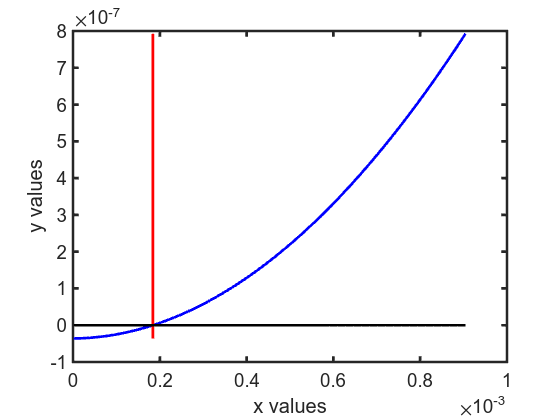

x=[0.01*t:t/10:t*5];
y=a*x.^2+b.*x+c;

plot(x,y,'b-','linewidth',2)
hold on
plot([t t],[min(y) max(y)],'r','linewidth',2)
plot(x,zeros(size(x)),'k','linewidth',2)
set(gca,'linewidth',2,'fontsize',14)
xlabel('x values','fontsize',15); ylabel('y values','fontsize',15)

%axis([min(x) max(x) min(y) max(y)])